% ---EXPLANATION OF PROGRAM---
% The initial purpose of the single_wave_phase_distance_final.mlx
% program is to be added to a SFCW radar system with an object in
% scene. It takes recieved radar waves across a set bandwidth (in 
% this case, 71-79GHz), and is able to, using amplitude and phase
% data, find the distance to the target to an exact degree. Using
% just amplitude, the resolution would be 2 cm, yet with this pro-
% gram, the resolution would be to whatever decimal MatLab rounds
% to, which is 1.0 * 10^-14 cm. These distances would be generated
% in one dimension, however to use this program before an azimuthal
% FFT, this could be changed to facilitate 2 or 3 dimensional mea-
% surements.

% Since this program was developed seperately from a SFCW radar,
% and meant to be implemented later, the radar waves are created
% digitally from a wave equation and a 'target distance' variable.
% These can easily be removed to connect to a real SFCW radar, as
% as the input waves would be digital.

%---HOW TO READ RESULTS---
% Input any distance you want into the 'target_distance' variable that is
% below the maximum unambiguous range. The program will then output the
% found distance from phase in the 'final distance' variable. Note that at
% high distances, specifically less than half a wavelength from the
% unabiguous range, this breaks down and will output half the actual
% distance. This is a quick fix, but I will need to run through the program
% with large numbers to do.

clc;
close all;
clear variables;

target_distance = 8.1111111;
c = physconst('lightspeed');
steps_across_bandwidth = 512;
sample_rate = 625000;
sample_time = 1 / sample_rate;
number_of_samples = 62500;
stop_time = sample_time * number_of_samples;
bw = 8*10^9;
range_res = c / (2 * bw);
unamb_range = range_res * steps_across_bandwidth;
step_size = bw / steps_across_bandwidth;
loc_freq = 500000;
f_x = 7.1*10^10;
f_x_array = linspace(f_x,f_x + bw,steps_across_bandwidth);
lambda = c./(f_x_array');
t = 0:sample_time:stop_time-sample_time;
steps_across_bandwidth_index = 0:steps_across_bandwidth - 1;
index_to_bandwidth = f_x + (steps_across_bandwidth_index * step_size);
freq_after_fft = linspace(0,1,number_of_samples).* sample_rate;
transmit_amp = 1;
rec_amp = 1;
rad_per_cycle = 2.*pi./lambda;
omega = (f_x_array .* 2 .* pi)'; %in radians per second
index_to_distance = steps_across_bandwidth_index * range_res;
phase = 0;

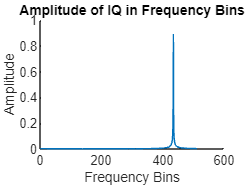

tau = (2 .* target_distance) ./ c;

rec_i = rec_amp .* cos(omega .* tau);
rec_q = rec_amp .* sin(omega .* tau);

iq_complex = complex(rec_i,-rec_q); %Flip the q wave because it is 
%the RECIEVED WAVE. If I was making the transmitted wave, it wouldn't
%be flipped. This is because once the wave hits the object in the scene
%the wave then rotates the opposite direction. For instance, a wave
%travelling clockwise, after hitting an object it would then be
%travelling counterclockwise. If you flip both the sin and the cos, the
%rotation of the actual phase wouldn't change, the phase would just start
%in a different place
iqar_complex = ifft(iq_complex);
iq_amp = abs(iqar_complex);


figure
hold on
plot(steps_across_bandwidth_index+1,iq_amp);
title('Amplitude of IQ in Frequency Bins');
ylabel('Amplitude');
xlabel('Frequency Bins');
hold off

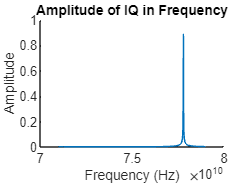


figure
hold on
plot(f_x_array,iq_amp);
title('Amplitude of IQ in Frequency');
ylabel('Amplitude');
xlabel('Frequency (Hz)');
hold off

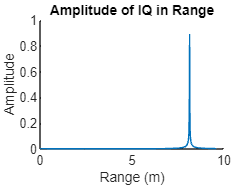


figure
hold on
plot(index_to_distance,iq_amp);
title('Amplitude of IQ in Range');
ylabel('Amplitude');
xlabel('Range (m)');
hold off

iq_phase = atan2(-imag(iq_complex),real(iq_complex));

i = 1;
while i <= steps_across_bandwidth
    if iq_phase(i) < 0
        iq_phase(i) = 2*pi + iq_phase(i);
    else
        iq_phase(i) = iq_phase(i);
    end
    i = i+1;
end

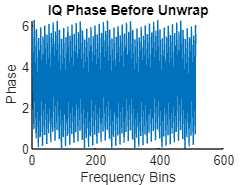

figure
hold on
plot(steps_across_bandwidth_index+1,iq_phase);
title('IQ Phase Before Unwrap');
ylabel('Phase');
xlabel('Frequency Bins');
hold off

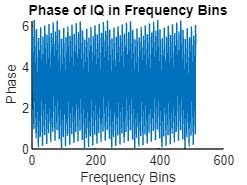


figure
hold on
plot(steps_across_bandwidth_index+1, iq_phase);
title('Phase of IQ in Frequency Bins');
ylabel('Phase');
xlabel('Frequency Bins');
hold off


[~, mirror_bin] = max(iq_amp);
mirror_range_amp = index_to_distance(mirror_bin);

mirror_range = [mirror_range_amp - range_res - 0.01, mirror_range_amp + range_res + 0.01];

range_rem = (iq_phase .* lambda)./(2*2*pi);
double_num_of_cycles = (mirror_range(1,1) - range_rem)./(lambda./2);
double_num_of_cycles = ceil(double_num_of_cycles);
pos_num_of_cycles = zeros(steps_across_bandwidth,steps_across_bandwidth);
i = 1;
double_pos_num_of_cycles = double_num_of_cycles;
while i <= steps_across_bandwidth
    y = 1;
    z = 1;
    while z == 1
        if i == steps_across_bandwidth
            z = z+1;
        elseif (((double_pos_num_of_cycles(i,y)+1)*lambda(i))/2)+range_rem(i) < mirror_range(1,2)
            double_pos_num_of_cycles(i,y+1) = double_pos_num_of_cycles(i,y) + 1;
            y = y+1;
        elseif (((double_pos_num_of_cycles(i,y)+1)*lambda(i))/2)+range_rem(i) > mirror_range(1,2)
            z = z+1;
        end
    end
    i = i+1;
end
[~,max_index] = max(double_pos_num_of_cycles,[],2);

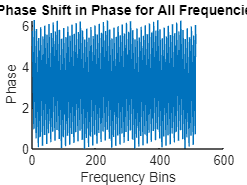

dist = range_rem + ((lambda./2) .* double_pos_num_of_cycles);
dist_diff(1:max_index(1)) = max(dist(1:end-1,1:max_index(1)),[],1) - min(dist(1:end-1,1:max_index(1)),[],1);
[~,min_bin] = min(dist_diff,[],2);
i = 2;
y = 1;
z = 1;
rn = 5;
dist2 = dist;
dist_index = 1;
test_dist = dist(dist_index);
max1 = size(dist,2);
max2 = size(dist,1);
while z == 1
    if max1 < dist_index
        z = z+1;
        program_didnt_work = 1;
    elseif i == steps_across_bandwidth
        z = z+1;
        program_didnt_work = 0;
    elseif max1 < y && max(dist(i,:)) > 0
        i = i + 1;
        y = 1;
    elseif max1 < y
        
        dist = dist2; %THIS IS THE LINE TO MARK TO WATCH THE DATA PROCESS--------------------------------------------------------------------------------------------------------
        dist_index = dist_index + 1;
        if max1 < dist_index
            z = z+1;
            program_didnt_work = 1;
        else
            test_dist = dist(1,dist_index);
        end
        y = 1;
        i = 2;
    elseif round(test_dist,5) == round(dist(i,y),5)
        dist_save(i-1,1) = dist(i,y);
        y = y + 1;
    elseif round(test_dist,5) ~= round(dist(i,y),5)
        dist(i,y) = 0;
        y = y+1;
    end
end
dist2 = dist(2:end-1,:);
final_distance = max(dist2,[],'all');

figure
hold on
plot(steps_across_bandwidth_index+1,iq_phase);
title('Phase Shift in Phase for All Frequencies');
ylabel('Phase');
xlabel('Frequency Bins');
hold off